# Práctica 5 - Prefijo cíclico

## 2.1. Convolución Circular 

1. Obtenga una señal aleatoria x[n], especificando su longitud N (en cualquier caso mayor o igual que 64) y el periodo de muestreo Ts. Obtenga y represente gráficamente su espectro, X[k], indicando en el eje de frecuencias las frecuencias positivas y negativas, así como la escala de frecuencias.

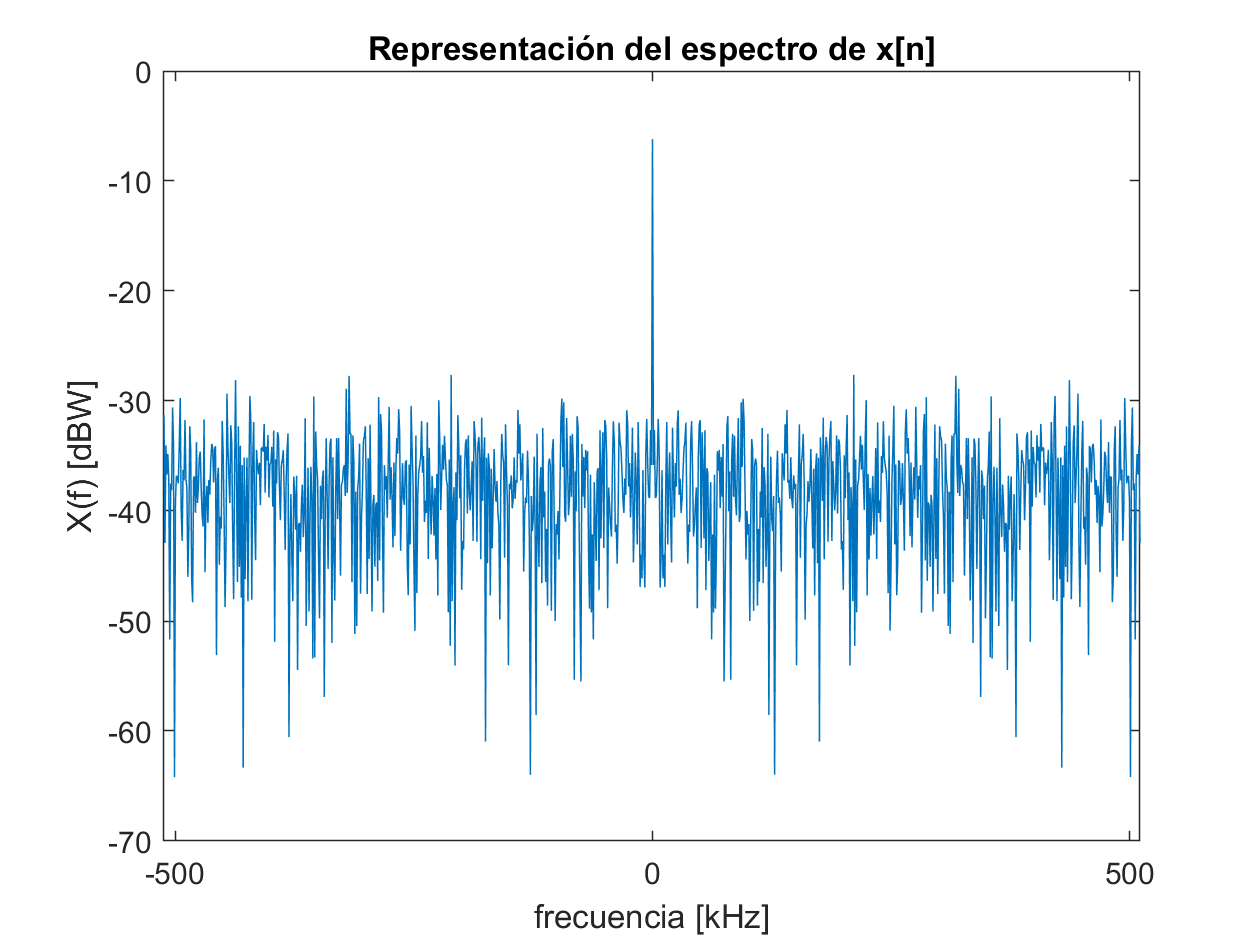

% Parametros
N = 1024; % Longitud
Ts = 0.001; % 1ms
x_n = randi([0 1],1,N); % señal aleatoria x[n]

% Espectro de x[n]
X_f = fft(x_n,N)/N;
f = -N/(2*Ts):1/Ts:N/(2*Ts)-1;
X_f_dBW = 20*log10(abs(X_f)); 

% Representacion del espectro x[n]
figure;
plot(f*1e-3,fftshift(X_f_dBW));
xlim([f(1)*1e-3 f(end)*1e-3]);
xlabel("frecuencia [kHz]");
ylabel("X(f) [dBW]");
title("Representación del espectro de x[n]");

2. Definición de la respuesta impulsiva del canal h[n]. Calcule y represente su espectro, H, de forma análoga a la de X.

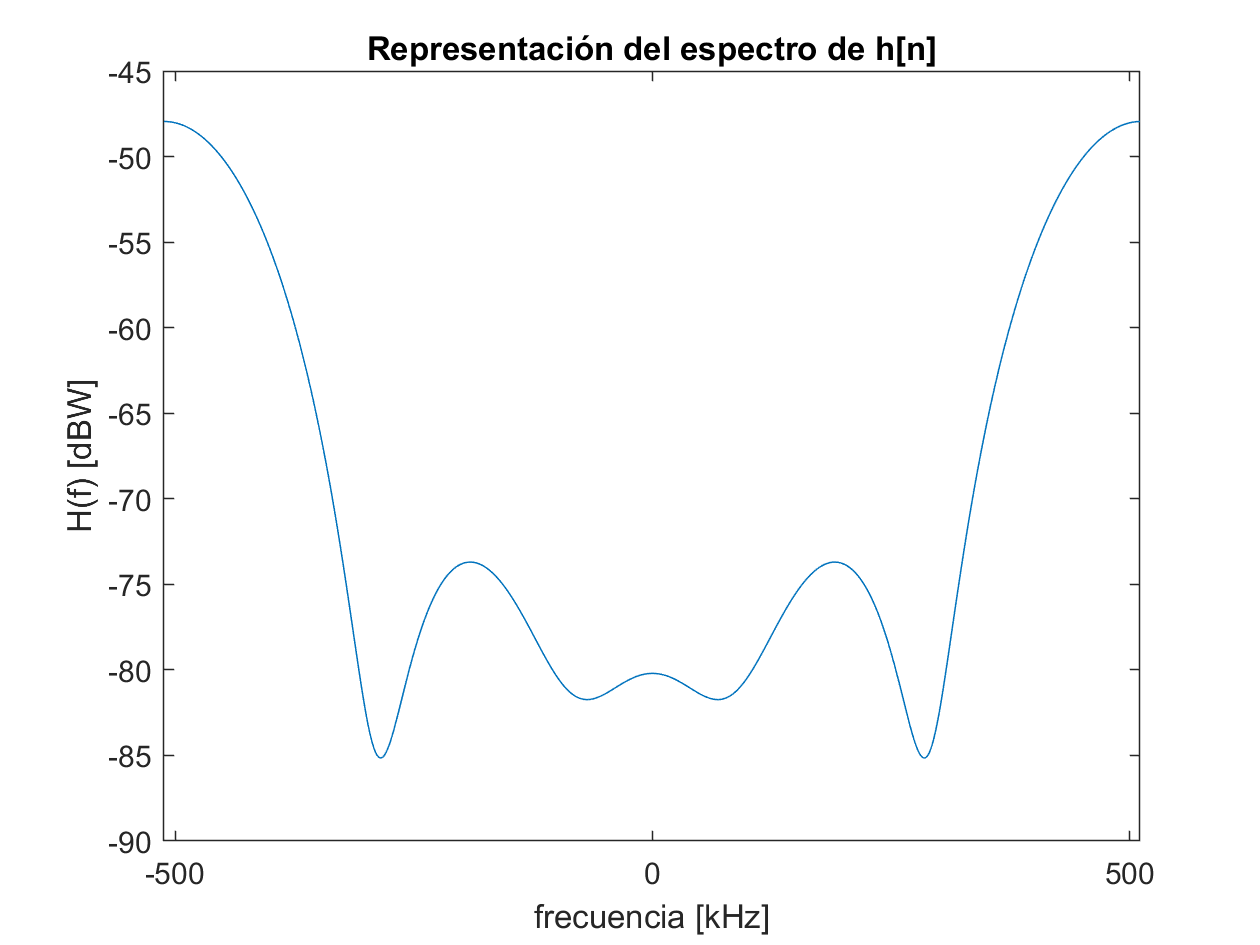

% Definicion del canal
h_n = [-0.1	0.3	-0.5 0.7 -0.9 0.7 -0.5 0.3 -0.1];

% Espectro de h[n]
H_f = fft(h_n,N)/N;
H_f_dBW = 20*log10(abs(H_f)); 

% Representacion del espectro h[n]
figure;
plot(f*1e-3,fftshift(H_f_dBW));
xlim([f(1)*1e-3 f(end)*1e-3]);
xlabel("frecuencia [kHz]");
ylabel("H(f) [dBW]");
title("Representación del espectro de h[n]");

3. Calcule la convolución lineal entre ambas, y = lconv(x,h), y su transformada de Fourier Y. Represente gráficamente Y de forma análoga a como lo ha hecho con X y H.

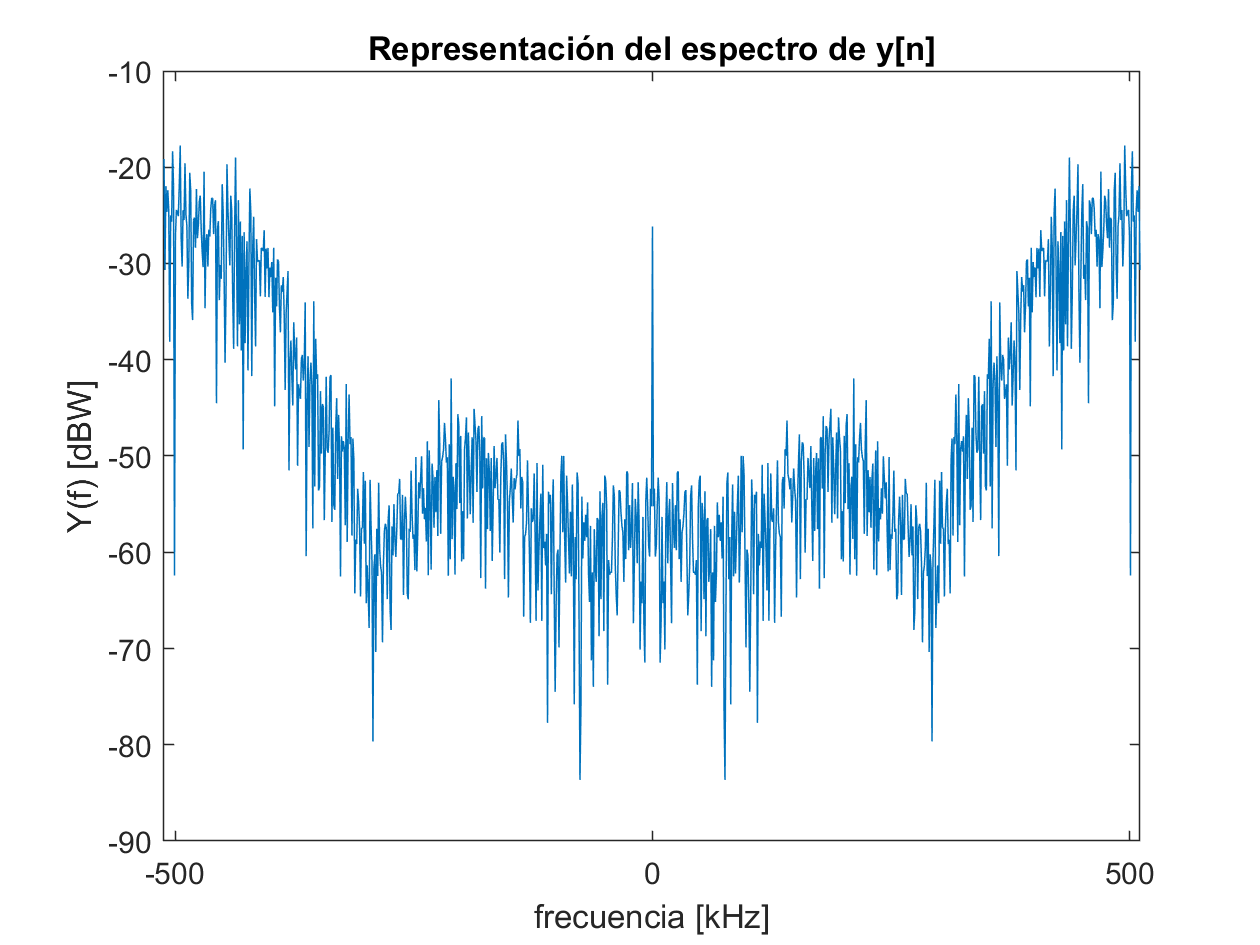

% Convolucion lineal entre x[n] y h[n]
y_n = conv(x_n,h_n);

% Espectro de y[n]
Y_f = fft(y_n,N)/N;
Y_f_dBW = 20*log10(abs(Y_f)); 

% Representacion del espectro y[n]
figure;
plot(f*1e-3,fftshift(Y_f_dBW));
xlim([f(1)*1e-3 f(end)*1e-3]);
xlabel("frecuencia [kHz]");
ylabel("Y(f) [dBW]");
title("Representación del espectro de y[n]");

4. Calcule la convolución circular yc = cconv(x,h). Puede utilizar la función cconv de Matlab, entendiendo cómo debe emplearse. Indíquese cómo se ha empleado. Calcule y represente su espectro Yc.

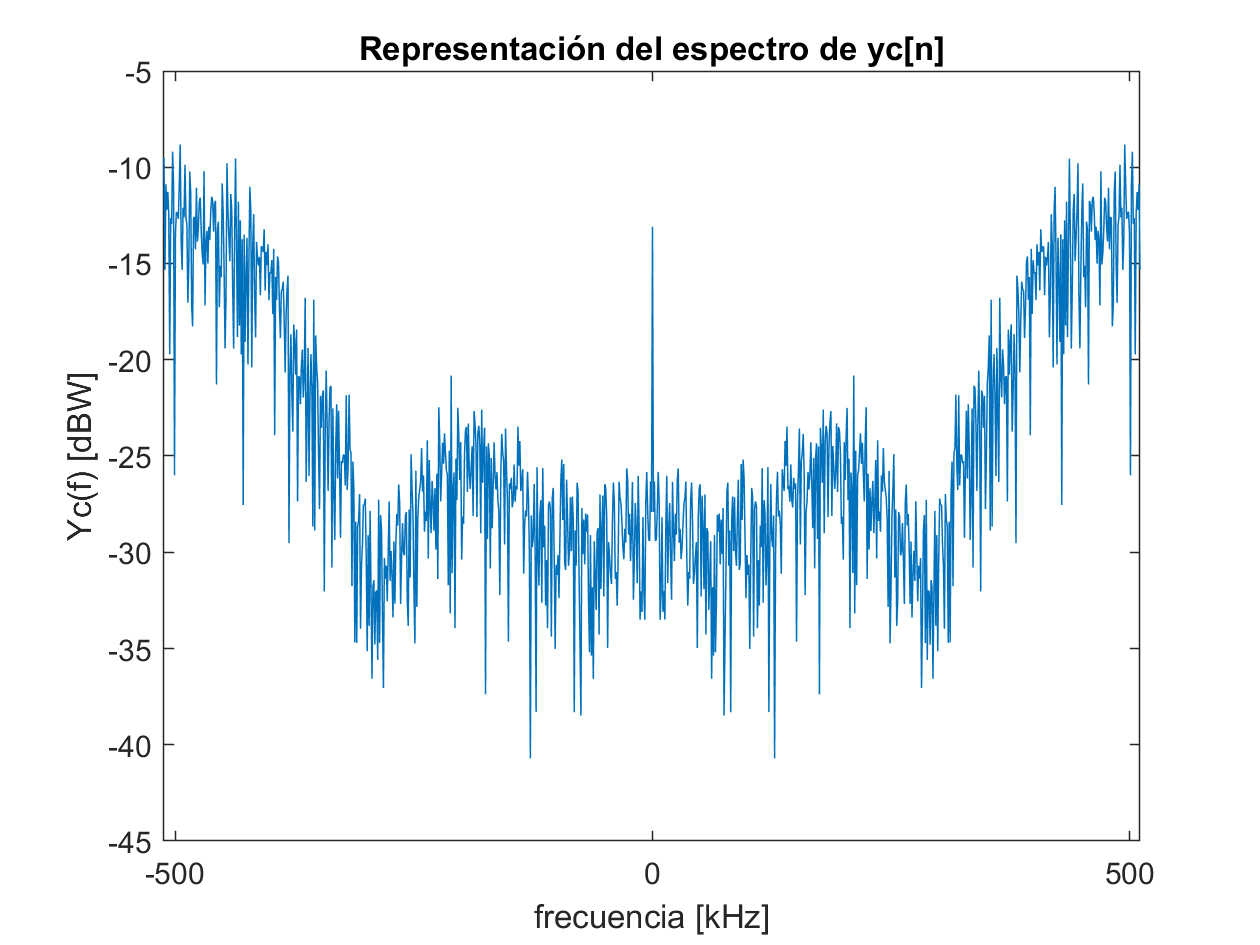

% Convolucion circular 
yc_n = cconv(x_n,h_n,N);

% Espectro de yc[n]
Yc_f = fft(yc_n,N)/N;
Yc_f_dBW = 10*log10(abs(Yc_f)); 

% Representacion del espectro yc[n]
figure;
plot(f*1e-3,fftshift(Yc_f_dBW));
xlim([f(1)*1e-3 f(end)*1e-3]);
xlabel("frecuencia [kHz]");
ylabel("Yc(f) [dBW]");
title("Representación del espectro de yc[n]");

5. Demuestre que X·H ≠ Y, y también que X·H = Yc

Ye_f = X_f.*H_f; % Operacion

% Comprobar si X·H ≠ Y
eq = isequal(Ye_f,Y_f);
if eq
    disp("Son equivalentes. X·H = Y.");
else
    disp("No son equivalentes. X·H ≠ Y.");
end

No son equivalentes. X·H ≠ Y.



% Comprobar si X·H = Yc
eq = isequal(Ye_f,Yc_f);
if eq
    disp("Son equivalentes. X·H = Yc.");
else
    disp("No son equivalentes. X·H ≠ Yc.");
end

No son equivalentes. X·H ≠ Yc.
